# Só para o Sid usar (melhor código aqui meus putos)

Aqui é Naive Bayes

% Ler o ficheiro CSV
data = readtable('dataset.csv');
% Exibir os nomes das colunas
%disp(data.Properties.VariableNames);

% Dividir a coluna única em duas: Frases e Categoria
splitData = split(data.Text, ' : ');

frases = splitData(:, 1); % Coluna com as frases
%categorias = splitData(:, 2); % Coluna com as categoria


categorias = cell(height(data), 1);
for ctg = 1 : height(data)
    categorias{ctg} = data.Category{ctg};
end
%disp(categorias);

%rrmover linhas duplicadas
%(fazer isto)


% ------------------------------
%dividir o dataset em treino e teste (60% treino, 40% teste)

% Total de linhas
numRows = size(data, 1);

% Gerar índices aleatórios
randIndices = randperm(numRows);

% Determinar limites para treino e teste
trainLimit = round(0.6 * numRows);

% Conjuntos de treino e teste
trainIndices = randIndices(1:trainLimit);
testIndices = randIndices(trainLimit + 1:end);

% Separar frases e categorias para treino
trainFrases = frases(trainIndices);
trainCategorias = categorias(trainIndices);

% Separar frases e categorias para teste
testFrases = frases(testIndices);
testCategorias = categorias(testIndices);

% Exibir resultados para validação
%disp('Conjunto de treino (frases):');
%disp(trainFrases);

%disp('Conjunto de treino (categorias):');
%disp(trainCategorias);

%disp('Conjunto de teste (frases):');
%disp(testFrases);

%disp('Conjunto de teste (categorias):');
%disp(testCategorias);

%--------------------------------

% Converter as frases para string para facilitar o processamento
trainFrases = string(trainFrases);
trainFrases = lower(trainFrases);
frasestoken = tokenizedDocument(trainFrases);
%customStopWords = [stopWords "there's" "someone"];
%customStopWords = string(customStopWords);

% Remover as stopwords usando removeStopWords
cleanfrasestoken = removeStopWords(frasestoken);
cleanfrases = joinWords(cleanfrasestoken);

trainFrases = string(cleanfrases);
%remover pontos finais das frases
trainFrases = regexprep(trainFrases, '\.$', '');
%remover virgulas das frases
trainFrases = regexprep(trainFrases, ',', '');


%converter texto em minusculas
trainFrases = lower(trainFrases);
disp(trainFrases);

    "there's person distress ferry "
    "someone trapped collapsed mine "
    "someone trapped fallen tree "
    "there's person stuck malfunctioning ride "
    "child choking breathe "
    "need assistance evacuating due flooding "
    "there's person experiencing severe dizziness "
    "someone struggling ocean "
    "need report child neglect "
    "there's vehicle blocking emergency access "
    "someone injured animal attack "
    "there's emergency power station "
    "found suspicious object "
    "someone bitten venomous snake "
    "there's electrical fire kitchen "
    "there's person trapped cave "
    "someone trapped heavy machinery "
    "stuck snowstorm "
    "there's emergency refinery "
    "someone trapped collapsed scaffold "
    "there's emergency dam "
    "there's gas leak office building "
    "someone threatening "
    "someone trapped collapsed bridge "
    "smoke coming engine compartment "
    "think there's hazardous material spill "
    "heard loud noises 


%------------------------------

%criar o vocabulário único das frases (lista de palavras únicas)
vocabulary = createVocabulary(trainFrases);
%remover strings vazias
vocabulary = vocabulary(vocabulary ~= "")

vocabulary = 288×1 string array
    "access"
    "accident"
    "accidents"
    "acting"
    "activity"
    "aggressive"
    "air"
    "airplane"
    "alarm"
    "alert"
    "allergic"
    "alley"
    "amusement"
    "animal"
    "apartment"
    "area"
    "assaulted"
    "assistance"
    "attack"
    "basement"
    "bathroom"
    "bee"
    "bitten"
    "blocking"
    "boating"
    "bomb"
    "break"
    "breathe"
    "breathing"
    "bridge"


%disp('Vocabulário único:');
%disp(vocabulary);

%------------------------------

%criar a matriz Bag-of-Words (número de ocorrências)
numFrases = length(trainFrases);
numWords = length(vocabulary);

%inicializar a matriz com zeros
matriz_ocorrencias = zeros(numFrases, numWords);

%preencher a matriz Bag-of-Words
for ctg = 1:numFrases
    %dividir a frase atual em palavras
    words = split(trainFrases{ctg});
    for j = 1:numWords
        %contar as ocorrências da palavra atual na frase atual
        matriz_ocorrencias(ctg, j) = sum(strcmp(words, vocabulary{j}));
    end
end

%exibir a matriz de ocorrências - linhas = frases || colunas = palavras
%ou seja, esta é a primeira linha da matriz
%1     0     0     0     0     0
%significa que na primeria frase aparece uma vez a primeria palavra da Bag-of-Words
disp('Matriz Ocorrências:');

Matriz Ocorrências:


disp(matriz_ocorrencias);

     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0    

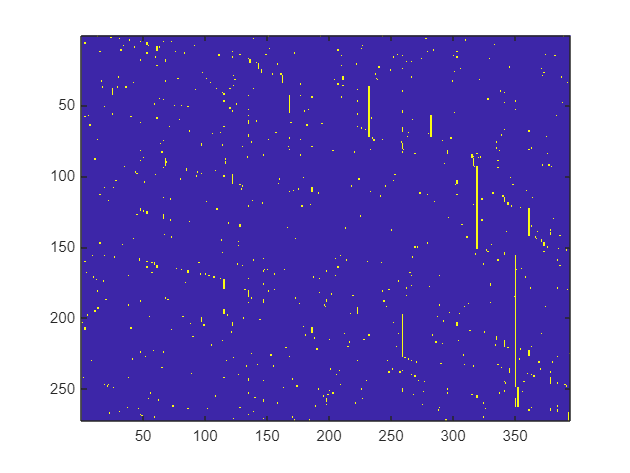

imagesc(matriz_ocorrencias)


% ------------------------------

% Criar um vetor com a frase correspondente a cada linha da matriz
% O vetor será simplesmente as frases, já que cada linha da matriz ocorrências
% corresponde a uma frase única.
fraseCorrespondente = trainFrases;
disp(trainFrases);

    "there's person distress ferry "
    "someone trapped collapsed mine "
    "someone trapped fallen tree "
    "there's person stuck malfunctioning ride "
    "child choking breathe "
    "need assistance evacuating due flooding "
    "there's person experiencing severe dizziness "
    "someone struggling ocean "
    "need report child neglect "
    "there's vehicle blocking emergency access "
    "someone injured animal attack "
    "there's emergency power station "
    "found suspicious object "
    "someone bitten venomous snake "
    "there's electrical fire kitchen "
    "there's person trapped cave "
    "someone trapped heavy machinery "
    "stuck snowstorm "
    "there's emergency refinery "
    "someone trapped collapsed scaffold "
    "there's emergency dam "
    "there's gas leak office building "
    "someone threatening "
    "someone trapped collapsed bridge "
    "smoke coming engine compartment "
    "think there's hazardous material spill "
    "heard loud noises 


% ------------------------------

% numero de casos favoraveis/ numero de casos possiveis 
% P(I) - prob de calhar I a dividir por todos
% P(B) - ...
% P(P) - ...

% Depois tenho que fazer a % P("palavra_à_escolha"|I) = (categoria palavra_à_escolha na classe I) / (numero de palavras na classe I)
% fazer isto para os três casos, I, P, B


%calcular P(I), P(B) e P(P)

%categorias
categorias_unicas = ['I', 'B', 'P'];

%probs das categorias
probabilidades_categoria = zeros(length(categorias_unicas), 1);

%contar ocorrências de cada categoria e calcular a probabilidade
for ctg = 1:length(categorias_unicas)
    categoria_count = sum(strcmp(trainCategorias, categorias_unicas(ctg))); %retorna 1 se forem iguais e soma todos os 1
    probabilidades_categoria(ctg) = categoria_count / length(trainCategorias); %casos favoraveis a dividir por casos totais
end


%exibir as probabilidades das categorias
disp('Probabilidades das categorias:');

Probabilidades das categorias:


for ctg = 1:length(categorias_unicas)
    fprintf('P(%s) = %.3f\n', categorias_unicas(ctg), probabilidades_categoria(ctg));
end

P(I) = 0.253
P(B) = 0.534
P(P) = 0.213


%calcular probs condicionadas

%criar matriz prob cond para cada palavra dada uma categoria
num_categorias = length(categorias_unicas);
prob_cond = zeros(num_categorias, numWords); %aqui linhas = categorias e colunas = palavras

%suavização de laplace (para evitar prob zero)
suavizacao_laplace = 1;

%calcular P(palavra | categoria)
for c = 1:num_categorias
    %vou filtrar frases que pertencem à categoria atual
    categoria_atual = categorias_unicas(c);
    indices_categorias = strcmp(trainCategorias, categoria_atual); %retorna 1 se for a mesma categoria
    frases_categoria = trainFrases(indices_categorias);

    %contar ocorrências de cada palavra nas frases da categoria
    total_palavras_categoria = 0;
    palavras_por_categoria = zeros(1, numWords); %counter para cada palavra

    for f = 1:length(frases_categoria)
        %dividir frase em palavras
        palavras = split(frases_categoria{f});

        %atualizar contadores
        total_palavras_categoria = total_palavras_categoria + length(palavras);

        for p = 1:numWords
            palavras_por_categoria(p) = palavras_por_categoria(p) + sum(strcmp(palavras, vocabulary{p}));
        end
    end

    %calcular probs cond
    prob_cond(c, :) = (palavras_por_categoria + suavizacao_laplace) ./ (total_palavras_categoria + numWords * suavizacao_laplace);
end


for ctg = 1:num_categorias
    fprintf('Probabilidades condicionais para a categoria %s:\n', categorias_unicas(ctg));
    for j = 1:numWords
        fprintf('P(%s | %s) = %.4f\n', vocabulary{j}, categorias_unicas(ctg), prob_cond(ctg, j));
    end
    fprintf('\n');
end

Probabilidades condicionais para a categoria I:


P(access | I) = 0.0020
P(accident | I) = 0.0039
P(accidents | I) = 0.0020
P(acting | I) = 0.0020
P(activity | I) = 0.0020
P(aggressive | I) = 0.0020
P(air | I) = 0.0020
P(airplane | I) = 0.0039
P(alarm | I) = 0.0039
P(alert | I) = 0.0039
P(allergic | I) = 0.0039
P(alley | I) = 0.0020
P(amusement | I) = 0.0039
P(animal | I) = 0.0039
P(apartment | I) = 0.0020
P(area | I) = 0.0020
P(assaulted | I) = 0.0020
P(assistance | I) = 0.0078
P(attack | I) = 0.0039
P(basement | I) = 0.0020
P(bathroom | I) = 0.0020
P(bee | I) = 0.0039
P(bitten | I) = 0.0039
P(blocking | I) = 0.0020
P(boating | I) = 0.0039
P(bomb | I) = 0.0020
P(break | I) = 0.0020
P(breathe | I) = 0.0020
P(breathing | I) = 0.0039
P(bridge | I) = 0.0020
P(broke | I) = 0.0020
P(broken | I) = 0.0020
P(building | I) = 0.0020
P(burning | I) = 0.0020
P(burns | I) = 0.0039
P(car | I) = 0.0020
P(carbon | I) = 0.0020
P(caught | I) = 0.0020
P(causing | I) = 0.0020
P(cave | I) = 0.0020
P(chemical | I) = 0.0020
P(chest | I) = 0.0039
P(child | I

Probabilidades condicionais para a categoria B:


P(access | B) = 0.0013
P(accident | B) = 0.0013
P(accidents | B) = 0.0013
P(acting | B) = 0.0013
P(activity | B) = 0.0013
P(aggressive | B) = 0.0026
P(air | B) = 0.0013
P(airplane | B) = 0.0026
P(alarm | B) = 0.0026
P(alert | B) = 0.0013
P(allergic | B) = 0.0013
P(alley | B) = 0.0013
P(amusement | B) = 0.0013
P(animal | B) = 0.0039
P(apartment | B) = 0.0026
P(area | B) = 0.0039
P(assaulted | B) = 0.0013
P(assistance | B) = 0.0039
P(attack | B) = 0.0013
P(basement | B) = 0.0039
P(bathroom | B) = 0.0026
P(bee | B) = 0.0013
P(bitten | B) = 0.0013
P(blocking | B) = 0.0039
P(boating | B) = 0.0013
P(bomb | B) = 0.0013
P(break | B) = 0.0013
P(breathe | B) = 0.0013
P(breathing | B) = 0.0013
P(bridge | B) = 0.0026
P(broke | B) = 0.0026
P(broken | B) = 0.0039
P(building | B) = 0.0090
P(burning | B) = 0.0052
P(burns | B) = 0.0013
P(car | B) = 0.0052
P(carbon | B) = 0.0026
P(caught | B) = 0.0026
P(causing | B) = 0.0013
P(cave | B) = 0.0026
P(chemical | B) = 0.0039
P(chest | B) = 0.0013
P(child | B

Probabilidades condicionais para a categoria P:


P(access | P) = 0.0043
P(accident | P) = 0.0043
P(accidents | P) = 0.0043
P(acting | P) = 0.0043
P(activity | P) = 0.0043
P(aggressive | P) = 0.0021
P(air | P) = 0.0043
P(airplane | P) = 0.0021
P(alarm | P) = 0.0021
P(alert | P) = 0.0021
P(allergic | P) = 0.0021
P(alley | P) = 0.0043
P(amusement | P) = 0.0021
P(animal | P) = 0.0021
P(apartment | P) = 0.0021
P(area | P) = 0.0021
P(assaulted | P) = 0.0043
P(assistance | P) = 0.0021
P(attack | P) = 0.0021
P(basement | P) = 0.0021
P(bathroom | P) = 0.0021
P(bee | P) = 0.0021
P(bitten | P) = 0.0021
P(blocking | P) = 0.0043
P(boating | P) = 0.0043
P(bomb | P) = 0.0043
P(break | P) = 0.0064
P(breathe | P) = 0.0043
P(breathing | P) = 0.0021
P(bridge | P) = 0.0021
P(broke | P) = 0.0021
P(broken | P) = 0.0021
P(building | P) = 0.0021
P(burning | P) = 0.0021
P(burns | P) = 0.0021
P(car | P) = 0.0043
P(carbon | P) = 0.0021
P(caught | P) = 0.0021
P(causing | P) = 0.0043
P(cave | P) = 0.0021
P(chemical | P) = 0.0043
P(chest | P) = 0.0021
P(child | P

% depois para finalizar naive bayes